# Baysian Optimisation

Use bayesian optimisation to find optimal set of input parameters

clear all
% load pressure and temperature models
load('both_models.mat')

% set bounds
[hc_lower, hc_upper] = deal(0.6, 2.4);
[wc_lower, wc_upper] = deal(0.2, 1.8);
[L_lower, L_upper] = deal(12, 108);
[Tamb_lower, Tamb_upper] = deal(25, 31.6);
[Q_lower, Q_upper] = deal(1272, 5040);
[Uin_lower, Uin_upper] = deal(0, 20);

## Define Variables

% define the optimization parameters and ranges
optimVars = [
    optimizableVariable('hc', [hc_lower hc_upper], 'Type', 'real');
    optimizableVariable('wc', [wc_lower wc_upper], 'Type', 'real');
    optimizableVariable('L', [L_lower L_upper], 'Type', 'real');
    optimizableVariable('Tamb', [Tamb_lower Tamb_upper], 'Type', 'real');
    optimizableVariable('Q', [Q_lower Q_upper], 'Type', 'integer');
    optimizableVariable('Uin', [Uin_lower Uin_upper], 'Type', 'real');
];

## Define Objective and Constraints

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.
Copying objective function to workers...
Done copying objective function to workers.
|=========================================================================================================================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Constraint1  | Constraint2  |           hc |           wc |            L |         Tamb |            Q |          Uin |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |              |              |              |              |
|================================================================================================================================================================================================

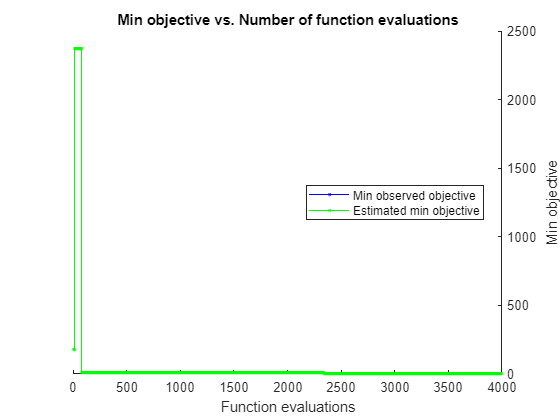


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 4000 reached.
Total function evaluations: 4000
Total elapsed time: 26694.9284 seconds
Total objective function evaluation time: 55.2694

Best observed feasible point:
      hc        wc        L        Tamb      Q       Uin  
    ______    ______    ______    ______    ____    ______

    1.7763    1.3505    84.629    31.153    4360    4.3229

Observed objective function value = 1.5537
Estimated objective function value = 1.5566
Function evaluation time = 0.009617
Observed constraint violations =[ -1.000000 -1.000000 ]

Best estimated feasible point (according to models):
      hc        wc        L        Tamb

% define Objective function
fun = @(T)objFcn(T, pressure_shallow_net, temp_shallow_net);

% run bayesopt
results = bayesopt(fun,optimVars,...
   'AcquisitionFunctionName','expected-improvement-plus',...
   'MaxObjectiveEvaluations',4000,...
   'IsObjectiveDeterministic',true, ...
   'NumCoupledConstraints',2,...
   'UseParallel',true);

## Obtain best hyperparams

optimisedInputs = bestPoint(results,'Criterion','min-observed')

optimisedInputs = 1×6 table
      hc        wc        L        Tamb      Q       Uin  
    ______    ______    ______    ______    ____    ______

    1.7763    1.3505    84.629    31.153    4360    4.3229


opt_ip = table2array(optimisedInputs)';
% Evaluate with the optimized inputs
pressure_drop = pressure_shallow_net(opt_ip)

pressure_drop = 1.5537

temperature = temp_shallow_net(opt_ip)

temperature = 58.7924

save('Run_4_bayesopt_4000.mat')

function [pressure_drop, constraints]= objFcn(T, press_net, temp_net)
    x_val = [T.hc; T.wc; T.L; T.Tamb; T.Q; T.Uin];
    pressure_drop = press_net(x_val);
    temperature = temp_net(x_val);
    
    % pressure constrain above 0
    if  pressure_drop >= 0
        pressure_lim = -1;  % feasible
    else 
        pressure_lim = 1;   % not feasible
    end

    % temp constrain btw 55 and 60
    if (temperature >= 55 && temperature <= 60)
        temp_range = -1;    % feasible
    else
        temp_range = 1;     % not feasible
    end
    constraints = [pressure_lim, temp_range];
end